usage: teamwork for week 6

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.4.11

clear all; close all; clc

**1.  请查阅Ridders方法**$\left[^1\right]$**， 并应用此算法求解以下方程, 请将你的结果和Matlab内置函数fzero的结果比较： **

    
$$$$
    T(x)=T_s+(T_i-T_s)\text{erf}\left(\frac{x}{2\sqrt{\alpha t_m}}\right)=0
    $$$$


**其中**$$T$$**是随位置**$$x$$**(用米计算)变化的温度函数，参数**$$\alpha=0.138\times 10^{-6} m^2 /s$**.  设起始温度**$$T_i=200^o$$**， 极限温度**$$T_s=-150^o$$**。时间间隔**$$t_m=60$$**天。误差函数**$$\text{erf}$$**的定义为**


$$    $$
   \text{erf}(x)=\frac{2}{\sqrt{\pi}}\int_0^x e^{-t^2}dt
    $$$$


解：

clear all;
format long
fun = @(t)(exp(-t.^2))

fun = 包含以下值的 function_handle :
    @(t)(exp(-t.^2))


erf = @(x)(2/sqrt(pi)*integral(fun, 0, x))

erf = 包含以下值的 function_handle :
    @(x)(2/sqrt(pi)*integral(fun,0,x))


T = @(x)(-150 + (200 + 150)*erf(x./(2*sqrt(0.138*(10^(-6))*60*24*3600))))

T = 包含以下值的 function_handle :
    @(x)(-150+(200+150)*erf(x./(2*sqrt(0.138*(10^(-6))*60*24*3600))))


x_1_check = fzero(T, 0)

x_1_check =    0.676961854481937


通过内置函数fzero求得解为$x=$0.676961m，故取Ridders方法的两个初始值分别为$x_0=0,x_1=1$

[x_1, flag_1] = Ridders(T, 0, 1, 1e-6, 10000)

Ridders method:
the root of f(x)=0 is x = 0.676962, the number of iterations is 10


x_1 =    0.676961854481937


flag_1 =     10


e_r_1 = relative_e(x_1, x_1_check)

相对误差为: 0.000000e+00

e_r_1 =      0


分析相对误差可以得到，通过Ridders方法求得的解和内置函数fzero求得的解基本相同，均为$x=$0.676961m

**2. 一个引人注意的想法是结合二分法和牛顿法 - 先应用二分法， 当达到一个设定的小区间后改用牛顿法来加快收敛速度。    **

**   请编写函数脚本`bisection_Newton.m`实现这样的算法： 设置初始试探区间**$$[a,b]$$**, 当使用二分法达到的试探区间是原来的一部分**$$s$$** (即区间长度为**$$s(b-a)$$**) 后采用牛顿法。 考虑到牛顿法有可能发散， 所以当牛顿法的结果使得试探区间在二分法结果之外时， 应该重新使用二分法。 **$$s$$**将作为函数的输入变量， 它的缺省值为0.1. **

**   尝试用你的函数在初始区间**$$[-10,15]$$**求解**$$\tan(x)=0$$**.**

解：

考虑弧度制的区间$[-10, 15]$作图容易发现不仅两个端点符号相同，而且在区间内函数并不连续，无法利用零点存在定理求解。故采用角度值$[-10^\circ,15^\circ]$进行求解。

clear all;
sample_2 = -10:pi/32:15

sample_2 =  -10.000000000000000  -9.901825229575319  -9.803650459150639  -9.705475688725956  -9.607300918301275  -9.509126147876595  -9.410951377451914  -9.312776607027233  -9.214601836602551  -9.116427066177870  -9.018252295753189  -8.920077525328509  -8.821902754903828  -8.723727984479147  -8.625553214054465  -8.527378443629784  -8.429203673205103  -8.331028902780423  -8.232854132355742  -8.134679361931060  -8.036504591506379  -7.938329821081698  -7.840155050657017  -7.741980280232337  -7.643805509807655  -7.545630739382974  -7.447455968958293  -7.349281198533612  -7.251106428108931  -7.152931657684250  -7.054756887259569  -6.956582116834888  -6.858407346410207  -6.760232575985526  -6.662057805560845  -6.563883035136164  -6.465708264711482  -6.367533494286802  -6.269358723862121  -6.171183953437440  -6.073009183012759  -5.974834412588078  -5.876659642163396  -5.778484871738716  -5.680310101314035  -5.582135330889353  -5.483960560464673  -5.385785790039991  -5.287611019615310  -5.1894

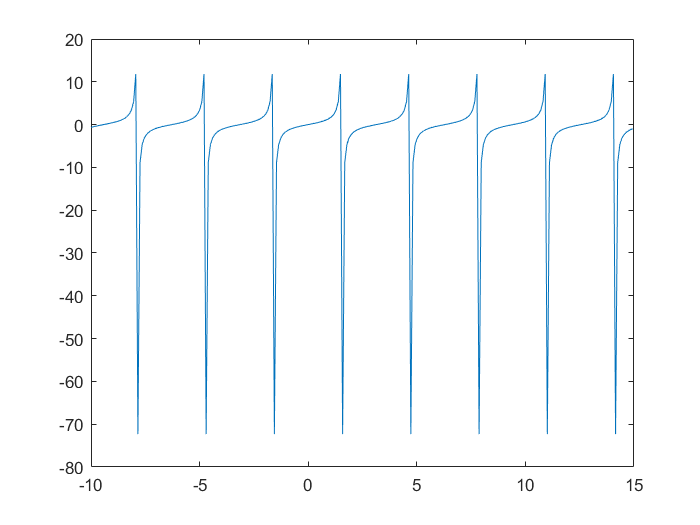

plot(sample_2, tan(sample_2))

high = -10 / 180 * pi

high =   -0.174532925199433


low = 15 / 180 * pi

low =    0.261799387799149


[x_2_1, flag_2_1] = bisection_Newton(@tan, 1e-6, 10000, high, low)

bisection_Newton:
s: 0.100000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19


x_2_1 =     -1.664475681382791e-07


flag_2_1 =     19


bisection_Newton:
s: 0.050000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s: 0.100000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s: 0.150000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s: 0.200000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s: 0.250000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s: 0.300000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s: 0.350000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s: 0.400000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s: 0.450000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s: 0.500000
the root of f(x)=0 is x = -0.000000, the number of iterations is 19
bisection_Newton:
s:

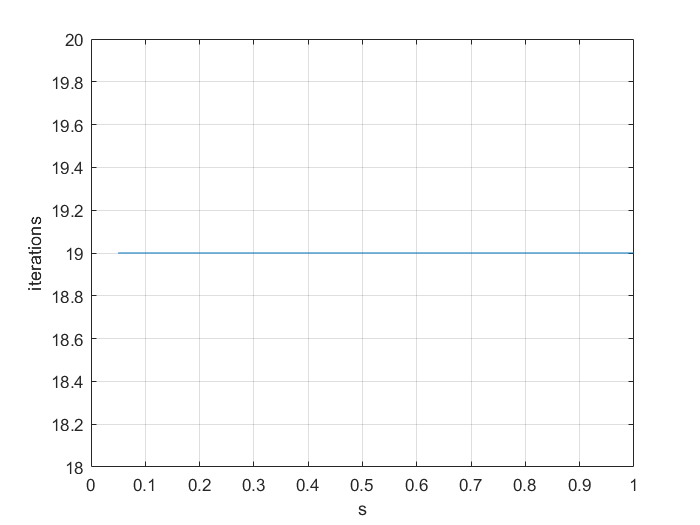

% s取不同值时的迭代次数
plot_bisection_Newton_s(@tan, 1e-6, 10000, high, low, 20)

求解得$x\approx0$

从图可得事实上s的选取，对在$x=0$的邻域内求解$$\tan(x)=0$$的迭代次数基本没有影响，均为19次。

**3. 运行以下程序，描述该程序解决的问题， 并在每行加入注释。**

解：

首先绘制两条曲线以及$y=x$进行观察。

clear all;
sample_3 = (-3:0.1:2)

sample_3 =   -3.000000000000000  -2.900000000000000  -2.800000000000000  -2.700000000000000  -2.600000000000000  -2.500000000000000  -2.400000000000000  -2.300000000000000  -2.200000000000000  -2.100000000000000  -2.000000000000000  -1.900000000000000  -1.800000000000000  -1.700000000000000  -1.600000000000000  -1.500000000000000  -1.400000000000000  -1.300000000000000  -1.200000000000000  -1.100000000000000  -1.000000000000000  -0.900000000000000  -0.800000000000000  -0.700000000000000  -0.600000000000000  -0.500000000000000  -0.400000000000000  -0.300000000000000  -0.200000000000000  -0.100000000000000                   0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000   1.100000000000000   1.200000000000000   1.300000000000000   1.400000000000000   1.500000000000000   1.600000000000000   1.700000000000000   1.800000000000000   1.9000


f_3_1 = @(x)-((24.43+1.8*x.^2)/3.2).^(1/3)

f_3_1 = 包含以下值的 function_handle :
    @(x)-((24.43+1.8*x.^2)/3.2).^(1/3)


f_3_2 = @(x)((5.92+2*x.^2)/3).^(1/3)

f_3_2 = 包含以下值的 function_handle :
    @(x)((5.92+2*x.^2)/3).^(1/3)


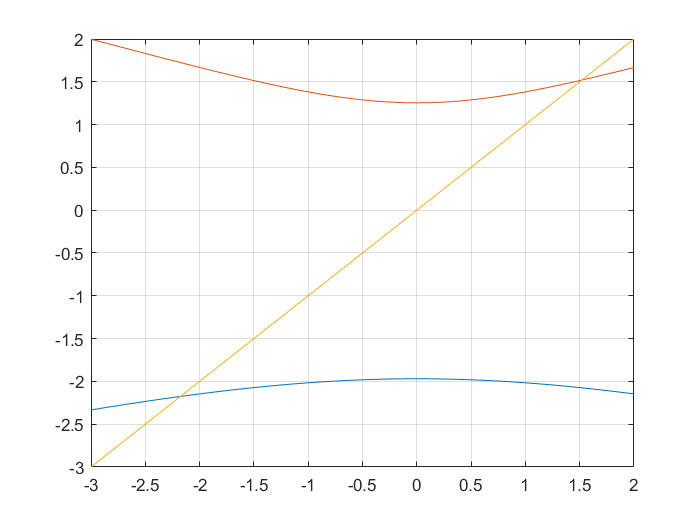

plot(sample_3, f_3_1(sample_3), sample_3, f_3_2(sample_3), sample_3, sample_3)
grid on

程序事实上是对非线性方程组$   \begin{cases}
   3.2y^3+24.43+1.8x^2=0\\
   3x^3-5.92-2y^2=0
   \end{cases}$，应用不动点迭代的方法求得数值解。首先将两式化为$   \begin{cases}
  y=-\sqrt[3]{\frac{24.43+1.8x^2}{3.2}}\\
  x=\sqrt[3]{\frac{5.92+2y^2}{3}}
   \end{cases}$，然后令$g_1=-\sqrt[3]{\frac{24.43+1.8x^2}{3.2}}$ ，$ g_2=\sqrt[3]{\frac{5.92+2y^2}{3}}$ 通过迭代公式$y^{(k)}=g_1(x^{(k-1)})$，$x^{(k)}=g_2(y^{(k-1)})$，并通过误差式$\sqrt{(x^{(k)}-x^{(k-1)})^2+(y^{(k)}-y^{(k-1)})^2}<\epsilon$ 判断是否达到误差上限，或当迭代次数达到最多次数限制时，停止迭代。

clear all;
g1 = @(v) -((24.43+1.8*v(2,1).^2)/3.2).^(1/3) % 迭代式g1

g1 = 包含以下值的 function_handle :
    @(v)-((24.43+1.8*v(2,1).^2)/3.2).^(1/3)


g2 = @(v) ((5.92+2*v(1,1).^2)/3).^(1/3)       % 迭代式g2

g2 = 包含以下值的 function_handle :
    @(v)((5.92+2*v(1,1).^2)/3).^(1/3)



tol = 1e-3; kmax = 10 % tol为误差上限，kmax为最多迭代次数

kmax =     10


v(:,1) = [-1;-2]      % 初始估计值v_0 = [y_0, x_0]

v =     -1
    -2


for k = 1:kmax     
   % 第k次迭代
   % 对应y_k = g1(x_k-1), x_k = g2(y_k-1)
   v(:,k+1) = [g1(v(:,k)); g2(v(:,k))];
   % 通过求2-范数判断是否达到误差上限
   if norm(v(:,k+1)-v(:,k)) < tol
       break
   end
end
% 显示通过定点迭代得到的结果
fprintf('y_0 = %f, x_0 = %f', v(1,k+1), v(2, k+1));

y_0 = -2.099834, x_0 = 1.700047

**4.应用定点迭代法求解非线性方程组**


$$   $$
   \begin{cases}
   2e^x+y&=0\\
   3x^2+4y^2&=8
   \end{cases}
   $$$$


**   提示： 1) 先绘制函数曲线， 确定根的大致位置。 2) 选择适当的辅助函数。 3) 请将结果与Matlab内置函数fsolve的求解结果比较.**

解：

（1）

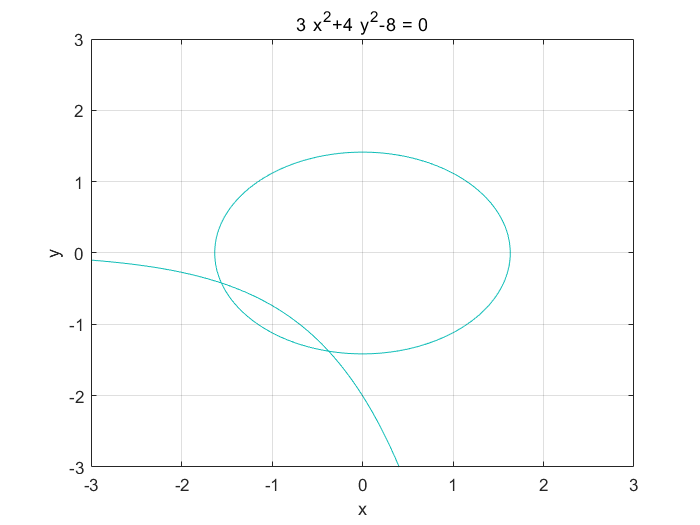

clear all;
ezplot('2*exp(x)+y')
hold on
ezplot('3*x^2+4*y^2-8')
axis([-3 3 -3 3])
grid on

通过绘制两条函数曲线可以得到方程组在区间$x\in[-2,-1],y\in[-1,0]$和$x\in[-1,0],y\in[-2,-1]$各有一解。

（2）

将方程组化为$   \begin{cases}
   y=-2e^x\\
  x=-\sqrt{\frac{8-4y^2}{3}}
   \end{cases}$，以及$\begin{cases}
   y=-\sqrt{\frac{8-3x^2}{4}}\\
  x=ln(-y/2)
\end{cases}$

对第一个解：分别令$   g_1=-2e^x\\
  g_2=-\sqrt{\frac{8-4y^2}{3}}$，选取初始点$[y_0=0, x_0=-2]$；

对第二个解：分别令$   g_1=-\sqrt{\frac{8-3x^2}{4}}\\
  g_2=ln(-y/2)$，选取初始点$[y_0=-1, x_0=-1]$；

通过迭代公式$y^{(k)}=g_1(x^{(k-1)})$，$x^{(k)}=g_2(y^{(k-1)})$的定点迭代法求解。

format long
clear all;
g_y1 = @(v)(-2*exp(v));
g_x1 = @(v)(-sqrt((8-4*v.^2)/3));
G1 = {g_y1 g_x1};
x0_4_1 = [0;-2];
[x_4_1, flag_4_1] = fixpoint_equation_set(G1, x0_4_1, 1e-6, 10000) 

fixpoint_equation_set:
the root of g(x)=x is


x_4_1 =   -0.420659143653259
  -1.559079213743325


flag_4_1 =     15



g_y2 = @(v)(-sqrt((8-3*v.^2)/4));
g_x2 = @(v)(log(-v./2));
G2 = {g_y2 g_x2};
x0_4_2 = [-1, -1];
[x_4_2, flag_4_2] = fixpoint_equation_set(G2, x0_4_2, 1e-6, 10000)

fixpoint_equation_set:
the root of g(x)=x is


x_4_2 =   -1.376739900121342
  -0.373429198846348


flag_4_2 =     16


通过定点迭代得到两个解分别为$\begin{cases}
y=-0.420659\\
x=-1.559079
   \end{cases}$和$\begin{cases}
y=-1.376739\\
x=-0.373429
   \end{cases}$

（3）

format long
clear all;
options = optimoptions('fsolve','Display',"iter");
fun = @root2d;
x0_1 = [0,-2];
x_4_check_1 = fsolve(fun, x0_1, options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3              64                           128               1
     1          6         1.41347       0.559017           14.2               1
     2          9      0.00757324       0.156926          0.952             1.4
     3         12     1.07007e-06      0.0174655         0.0112             1.4
     4         15     3.45203e-14    0.000235482          2e-06             1.4
     5         18     7.90833e-29    4.37002e-08       9.74e-14             1.4

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

x_4_check_1 =   -0.373428741127585  -1.376740074042629


x0_2 = [-2, 0];
x_4_check_2 = fsolve(fun, x0_2, options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         16.0733                          47.9               1
     1          6        0.730132        0.49128           8.54               1
     2          9      0.00185126       0.115382          0.403            1.23
     3         12     4.01899e-08     0.00772724        0.00187            1.23
     4         15     1.66867e-17    3.50118e-05       3.81e-08            1.23

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<<a href = "ma

x_4_check_2 =   -1.559079091427916  -0.420659352712557


通过matlab内置fsolve函数求得方程组两个解分别为$\begin{cases}
y=-1.376740\\
x=-0.373428
   \end{cases}$和$\begin{cases}
y=-0.420659\\
x=-1.559079
   \end{cases}$，证明定点迭代法求得的解基本正确。

**************************************************functions**********************************************

Ridders：Ridders方法

given two values $x_0$ and $x_2$，$f(x_0)f(x_2)<0$，calculate the midpoint$x_1 = (x_0+x_2)/2$.

a new value $x_3$between $x_0$and$x_2$，$x_3=x_1+(x_1-x_0)\frac{sign[f(x_0)]f(x_1)}{\sqrt{f(x_1)^2-f(x_0)f(x_2)}}$，use $x_3$ and whichever of $x_0$ and $x_2$ has function value of opposite sign to $f(x_3)$ in the next step of the iteration.

args：

    f：需要寻根的函数

    x0：初始值1

    x2：初始值2

    epsilon：误差上限

    max_n：最多计算的次数

output：

当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

当$flag=-2$，表示初始区间不存在根，$answer=NaN$；

其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = Ridders(f, x0, x2, epsilon, max_n)
    fprintf('Ridders method:\n');
    count = 0; % 迭代次数
    if(f(x0)*f(x2) > 0) % 如果符号相同则无法求解
        fprintf('区间内不存在根！');
    elseif(f(x0) == 0)
        count = -1; answer = x0;
    elseif(f(x2) == 0)
        count = -1; answer = x2;
    else %判断迭代次数小于最多计算次数；同时是否满足误差
        while(count < max_n && abs(x0 - x2) > epsilon)
            count = count + 1; 
            x1 = (x0 + x2) / 2;
            if(f(x1) == 0)
                x0 = x1; x2 = x1; break;
            end
            x3 = x1 + (x1 - x0)*sign(f(x0))*f(x1)/sqrt(f(x1)^2-f(x0)*f(x2));
            if(f(x3) == 0)
                x0 = x3; x2 = x3; break;
            end
            % 判断下一步迭代的x0和x2
            
            if(f(x3)*f(x0) > 0 && f(x3)*f(x2) > 0)
                if(f(x1)*f(x0) <= 0)
                    x2 = x1;
                else
                    x0 = x1;
                end
                
            elseif(f(x3)*f(x0) < 0)
                x2 = x3;
            elseif(f(x3)*f(x1) < 0)
                x0 = x1;
                x2 = x3;
            elseif(f(x3)*f(x2) < 0)
                x0 = x3;
            end
        end
    end
    % 
    switch count
        case max_n
            flag = -1; answer = NaN;
            fprintf('it may not converge or the iterations are not enough!\n')
        case 0
            flag = -2; answer = NaN;
        otherwise
            flag = count; answer = (x0 + x2) / 2;
            fprintf('the root of f(x)=0 is x = %f, the number of iterations is %d\n', answer, count);
    end
    
end

bisection_Newton：设置初始试探区间$[a,b]$，当使用二分法达到的试探区间是原来的一部分即区间长度为$s(b-a)$后采用牛顿法。考虑到牛顿法可能发散，所以当牛顿法的结果在二分法试探区间之外时，应该用二分法的结果代替牛顿法。

args：

    f：寻根的函数

    epsilon：误差上限

    max_n：最多计算步数

    high：二分法区间上限

    low：二分法区间下限

    s：二分法试探程度 default：0.1

output：

当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

当$flag=-2$，表示初始区间不存在根，$answer=NaN$；

其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = bisection_Newton(f, epsilon, max_n, high, low, s)
    fprintf('bisection_Newton:\n');
    if nargin < 6 % nargin:函数输入变量的个数
        s = 0.1;
    end
    fprintf('s: %f\n', s);
    %计算一阶导数
    syms x;
    fun = f(x);
    df = matlabFunction(diff(fun));
    
    %求根
    count = 0;
    length = s*abs(high - low);
    if(f(high)*f(low) > 0)
        fprintf('二分法区间不存在根！');
    elseif(f(high) == 0)
        count = -1; answer = high;
    elseif(f(low) == 0)
        count = -1; answer = low;
    else
        mid = (high + low) / 2;
        while(count < max_n && abs(high - low) > length && f(mid) ~= 0)
            count = count + 1;
            if(f(high)*f(mid) < 0)
                low = mid;
            else
                high = mid;
            end
            mid = (high + low) / 2;
        end
        while(count < max_n && abs(high - low) > epsilon && f(mid) ~= 0)
            count = count + 1;
            mid = mid - f(mid)/df(mid);
            
             % 如果迭代结果在二分范围外则换为(high + low)/2，并根据迭代结果更新high和low
            if(mid > high || mid < low)
                mid = (high + low) / 2;
            end
            if(f(high)*f(mid) < 0)
                low = mid;
            else
                high = mid;
            end
        end
    end
    switch count
        case max_n
            flag = -1; answer = NaN;
            fprintf('it may not converge or the iterations are not enough!\n')
        case 0
            flag = -2; answer = NaN;
        otherwise
            flag = count; answer = mid;
            fprintf('the root of f(x)=0 is x = %f, the number of iterations is %d\n', answer, count);
    end
end

plot_bisection_Newton_s：观察不同s对收敛次数的影响

args：

    f：寻根的函数

    epsilon：误差上限

    max_n：最多计算步数

    high：二分法区间上限

    low：二分法区间下限

    n：采样点的个数即每个点的间隔为$1/n$

function plot_bisection_Newton_s(f, epsilon, max_n, high, low, n)
    s = 1/n:(1/n):1;
    flag = zeros(size(s));
    for i=1:length(s)
        [~, flag(i)] = bisection_Newton(f, epsilon, max_n, high, low, s(i));
    end
    plot(s, flag)
    xlabel('s')
    ylabel('iterations')
    grid on
end

计算相对误差的函数，并显示

args:

    x_approx：估计值

    x_real：真值

function output = relative_e(x_approx, x_real)
    output = (x_approx - x_real .* ones(size(x_approx)))./x_real;
    fprintf("相对误差为: %e" , output);
end

fixpoint_equation_set：应用定点迭代法求解非线性方程组


$$   \begin{cases}
f_1(x_1,x_2,\dots,x_n)=0\\
f_2(x_1,x_2,\dots,x_n)=0\\
\dots\\
f_n(x_1,x_2,\dots,x_n)=0
   \end{cases}$$


args：

    G：一个函数向量（元胞数组）$\{g_1(x_2,\dots,x_n),g_2(x_1,x_3,\dots,x_n),\dots,g_n(x_1,x_2,\dots,x_{n-1})\}$，其中函数满足$x_i=g_i(x_1,x_2,\dots,x_{i-1},x_{i+1},\dots,x_n)$

    v：初始迭代向量$[x_1^{(0)};x_2^{(0)};\dots;x_n^{(0)}]$

    epsilon：误差上限，当满足$\sqrt{\sum_{i=1}^{n}{(x_i^{(k)}-x_i^{(k-1)})^2}}<\epsilon$时，停止迭代

    max_n：最多迭代次数

output：

当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = fixpoint_equation_set(G, x0, epsilon, max_n)
    fprintf('fixpoint_equation_set:\n');
    count = 0;
    v(:,1) =  x0; 
    while(count < max_n)
        count = count + 1;
        % 对于每个g函数，分别进行迭代
        for k = 1:length(G)
            index = 1:length(G);
            index(:,k)=[]; % 清除第k列
            g = G{k}; % 令g对于g_k
            v(k, count+1) = g(v(index, count)); % v的第k行第c+1列=g_k(v的第c列除去第k行)
        end
        if norm(v(:, count+1)-v(:, count)) < epsilon
            break
        end
    end
    
    if(count == max_n)
        flag = -1; answer = NaN;
        fprintf('it may not converge or the iterations are not enough!\n');
    else
        flag = count; answer = v(:,count+1);
        fprintf('the root of g(x)=x is\n');
    end
end

root2d：第四题用于fsolve求解的输入函数$   $$
   \begin{cases}
   2e^x+y&=0\\
   3x^2+4y^2&=8
   \end{cases}
   $$$

function F = root2d(x)
    F(1) = 2*exp(x(1)) + x(2);
    F(2) = 3*x(1)^2 + 4*x(2)^2 - 8;
end